clc;
clear;

## Read Me

This calculator is based off of the following formulas and testing data from: [12.2.6. Potted Inserts in Cored Laminates - Abbott Aerospace Canada Ltd](https://www.abbottaerospace.com/aa-sb-001/12-joints/12-2-mechanically-fastened-joints/12-2-6-potted-inserts-in-cored-laminates/).

Calculator was validated on XX/XX/XX. The data from the tests can be found here: 

Built by Aidan McLaughlin 3/27/2023

## Define Loads and Mtl. Properties

P=1124; %compressive/tensile load [lbs]
Q=0; %shear load [lbs]
M=0; %moment 
T=0; %torque
SF=1.25; %safety Factor


syms bi; %variable for effective potting radius and insert radius !!DO NOT TOUCH!!

Sc=0.1875; %in, Size of Core cell
c=0.625;%in, Core thickness
Gc=6000;%psi, shear Modulus core
Es= 4000000;%psi, facing sheet young's modulus
vs=0.3; %facing sheet poissons ratio
Twcrit= 600; %psi, minimum core shear strength				
f =	0.05; %in, face sheet thickness				
Sigma_fy = 1200; %psi, face sheet yield strength. For composite face sheets the interlaminar shear strength can be used				
t0= 0.002; %in, foil thickness core
T0crit= 23000;%psi, Core material shear strength (normally AL)



## Effective Potting Radius Calculations

bp= 0.93192*bi+0.874*Sc-0.66151;
bR=bi+0.35*Sc;

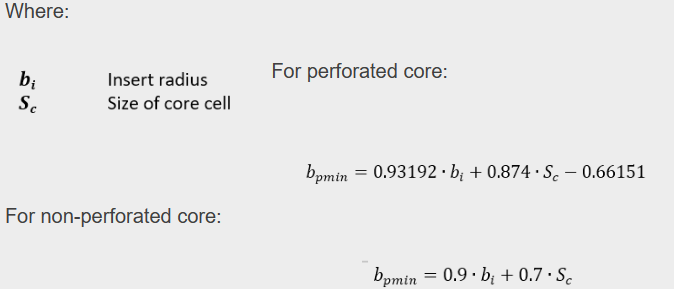

## Compressive Loading Calculations

 Beta=c/f;
 Alpha=(1/f)*sqrt((Gc/Es)*12*(1-vs^2)*(1+Beta/2));
 Tnom=P/(2*pi*bp*c);
 Cfactor= Beta/(Beta+1);

 %cant figure matlab out so made dummy b variable based on worst case
 %scenario (get the highest K value) to make Pcrit as small as possible
 dummyb=1;%1in pot radius
 r=linspace(0.25,9,100);
 K=(dummyb./r).*(1-sqrt(r./dummyb).*exp(Alpha.*(dummyb-r)));
 Tau=Tnom.*Cfactor.*K;
 %plot(Tau,r);
 Kmax=max(K)

Kmax =    0.660747957890395


 %Tmax=max(Tau);

 PSS=(2*pi*bp*c*Twcrit)./(Cfactor*Kmax);

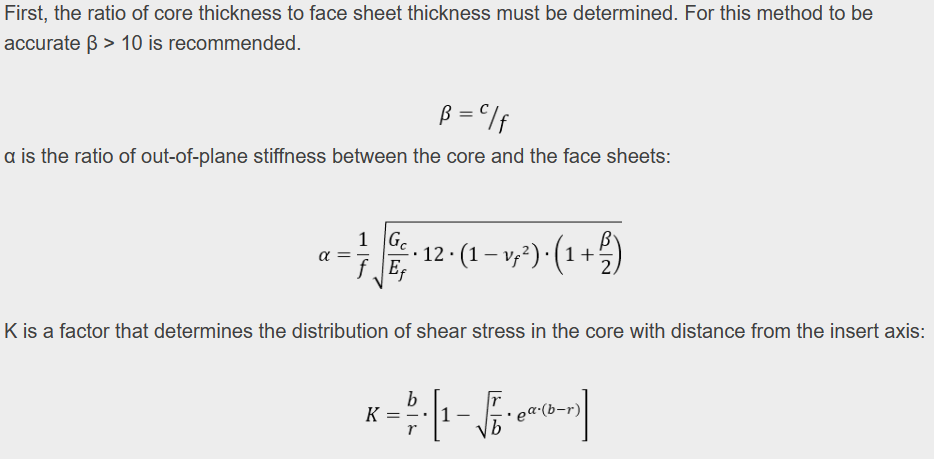

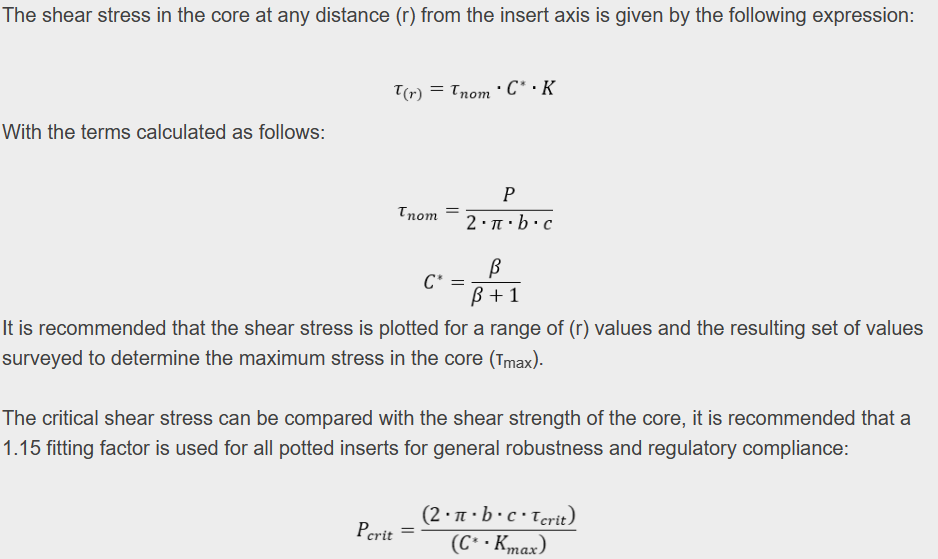

## Shear Loading Calculations

Qss=8*(bp^2)*Twcrit+2*f*bp*Sigma_fy;

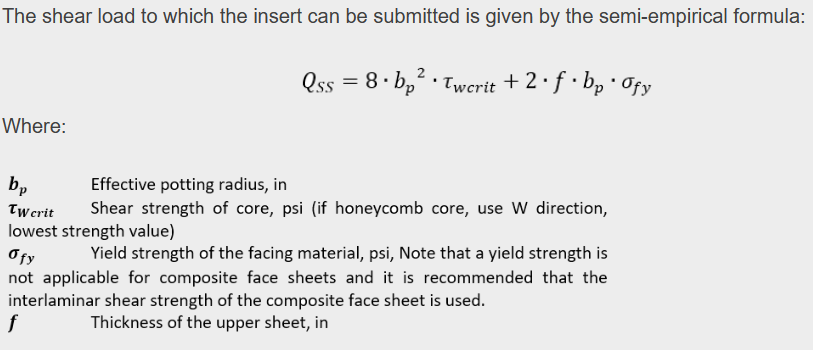

## Moment Loading Calculations

 Mss=PSS*bi;

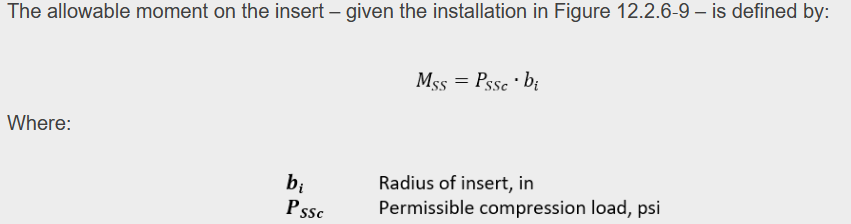

## Torsional Loading Calculations

  Tss=4*pi*(bR^2)*t0*T0crit;

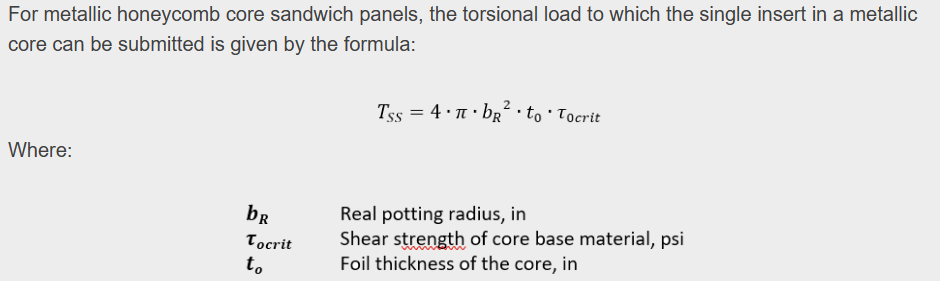

## Solve for Insert Radius

  eqn1 = ((P./PSS)^2 + (Q./Qss)^2 + (M./Mss)^2 +(T./Tss)^2)==SF;

  format long;
  Potting_Radius= max(double(solve(eqn1,bi,'Real', true)))

Potting_Radius =    0.814102191944590